# **Práctica 1: Análisis de la Respuesta Temporal de un Sistema de Control Digital**

Las practicas de la asignatura Control con Computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. La sesión P3 se dedica al diseño de controladores PID.

**OBJETIVO: Análisis de la respuesta temporal de un sistema de control digital para diferentes periodos de muestreo. Análisis de la precisión y de la estabilidad.**

**En esta sesión el estudiante ha de:**

- **Familiarizarse con el sistema: con la planta de tiempo continuo y con el uso del computador como generador de señales, osciloscopio y controlador digital.**

- **Evaluar las prestaciones (precisión y estabilidad) del sistema en función del periodo de muestreo.**

% Alternar entre los datos del experimento y los del directorio Resultados
% Si desea usar los datos del directorio Resultados = false
% Si desea usar datos propios = true
useExperimentalData = false;

# Ejercicio 1: Respuesta del sistema en lazo abierto para la señal del tacómetro.

Abrir y ejecutar el modelo P1_Ex1.slx. Comprobar que es la respuesta típica de un sistema de primer orden y cómo varía la ganancia estática si aplicamos al motor el freno magnético. Identificar la constante de tiempo $\tau_0$ y la ganancia estática $K_0$ para una entrada escalón de 1V. 

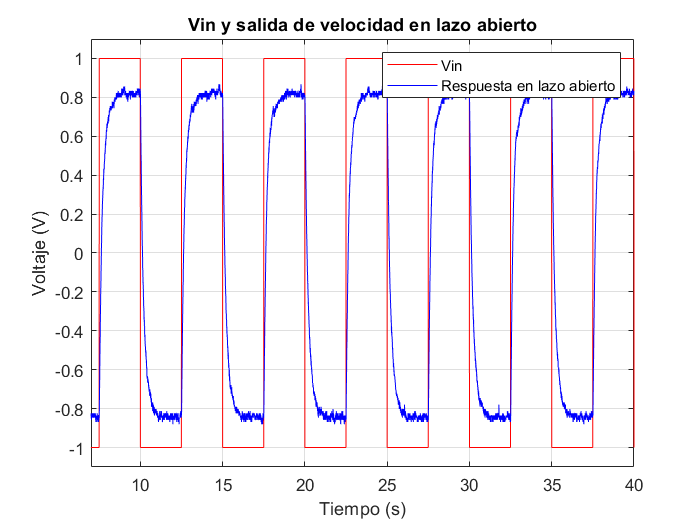

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

% Dibujar la respuesta del motor
if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'E1']);
    open P1_Ex1.slx;
    run P1_Ex1.slx;
else
    FileName   = 'OpenLoopResponse.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex1'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
xlim([7 40]); ylim([-1.1 1.1]);
grid on
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Vin y salida de velocidad en lazo abierto');
legend('Vin','Respuesta en lazo abierto');

% Aplicación del freno en lazo abierto
if useExperimentalData
    % Usar Simulink 
    addpath([pwd filesep 'E1']);
    open P1_Ex1.slx;
    run P1_Ex1.slx;
else
    FileName   = 'OpenLoopBrake.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex1'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

Como podemos ver, la salida se asemeja a la respuesta de un sistema de primer orden siendo la siguiente la estructura de su función de transferencia.


$$\frac{V_{\mathrm{out}} \left(s\right)}{V_{\mathrm{in}} \left(s\right)}=\frac{k}{\tau s+1}$$


Para este caso práctico se ha obtenido la siguiente función de transferencia.


$$\frac{V_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}=\frac{0\ldotp 82}{0\ldotp 26s+1}$$


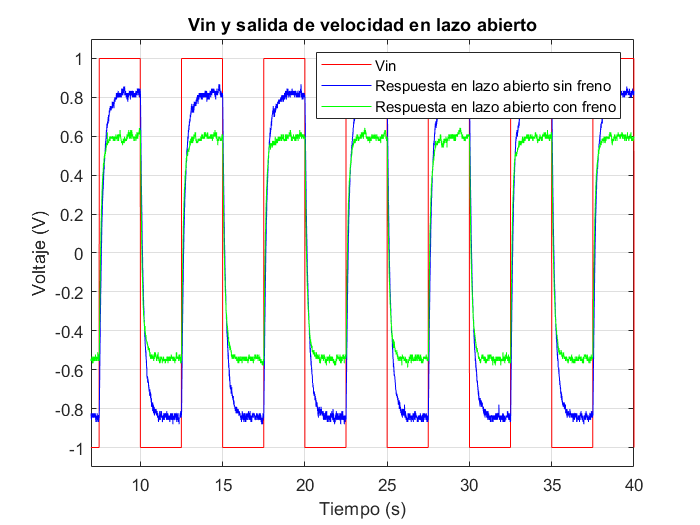

figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
plot(OpenLoopBrake.time,[OpenLoopBrake.signals.values(:,2,:)],'g')
xlim([7 40]); ylim([-1.1 1.1]);
grid on
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Vin y salida de velocidad en lazo abierto');
legend('Vin','Respuesta en lazo abierto sin freno','Respuesta en lazo abierto con freno');

Por otra parte, en el caso de lazo abierto, esta ganancia varía dependiendo del freno. Como se puede ver en la imagen, si aplicamos el freno, la ganancia se reducirá considerablemente.

# Ejercicio 2: Respuesta del sistema en lazo cerrado con realimentación de velocidad.

Abrir y ejecutar el modelo P1_Ex2.slx. Comprobar cómo varía el error en estado estacionario para Kp= 1, 2, 5 y 10, cambiando el bloque "Controlador Proporcional"

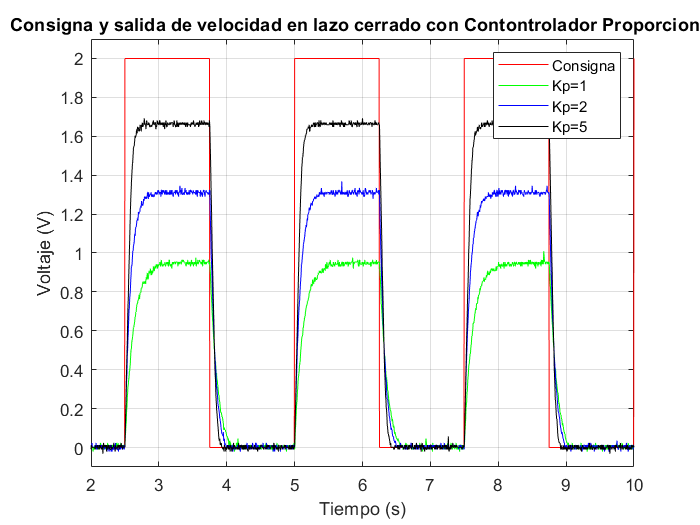

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Usar Simulink 
    addpath([pwd filesep 'E2']);
    open P1_Ex2.slx;
    run P1_Ex2.slx;
else % Cargar variables
    FileName   = 'Kp1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
  %  FolderName = [pwd filesep '..' filesep '..' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File); 
    
    FileName   = 'Kp2.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Kp5.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex2'];
    File       = fullfile(FolderName, FileName);
    load(File); 
end


% señales de salida
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,1,:)],'k')
xlim([2 10]); ylim([-0.1 2.1]);
grid on
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=5');

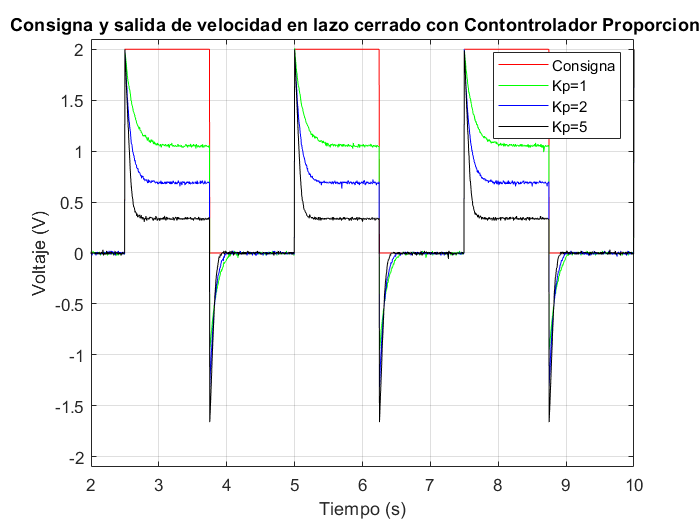


% señales de error
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,2,:)],'k')
xlim([2 10]); ylim([-2.1 2.1]);
grid on;
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=5');

Como se puede ver en las imágenes anteriores, a mayor Kp, la respuesta es más rápida y el error en estado estacionario menor.

# Ejercicio 3: Evaluación experimental de las prestaciones del sistema en lazo cerrado con realimentación de velocidad. 

Abirir y ejecutar el modelo P1_Ex3.slx. Evaluar cómo varía la precisión y la estabilidad del sistema para diferentes periodos de muestreo.

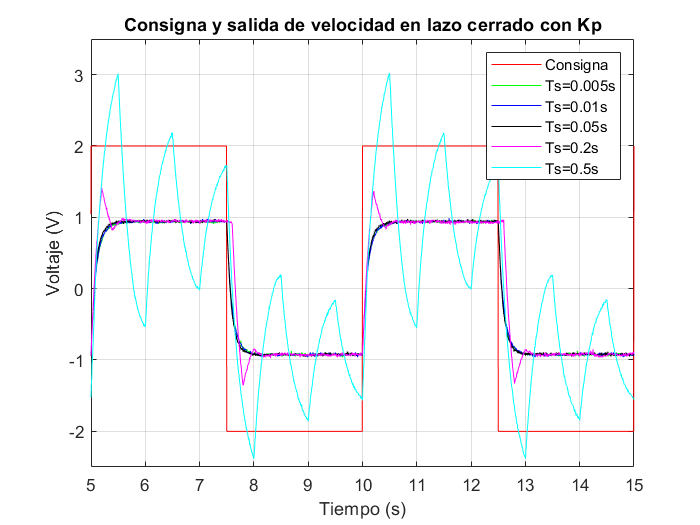

% Inicialización de variables
Tg= 0.005; % Tiempo de graficación [seg]
Ts=0.01; % Tiempo de muestreo
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Usar Simulink 
    addpath([pwd filesep 'E3']);
    open P1_Ex3.slx;
    run P1_Ex3.slx;
else % Cargar variables
    FileName   = 'Ts5ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);   

    FileName   = 'Ts10ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts50ms.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts02s.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts05s.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex3'];
    File       = fullfile(FolderName, FileName);
    load(File);
end


% salida
figure()
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,3,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,3,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,3,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,3,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,3,:)],'c')
xlim([5 15]);ylim([-2.5 3.5]);
grid on;
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de velocidad en lazo cerrado con Kp');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

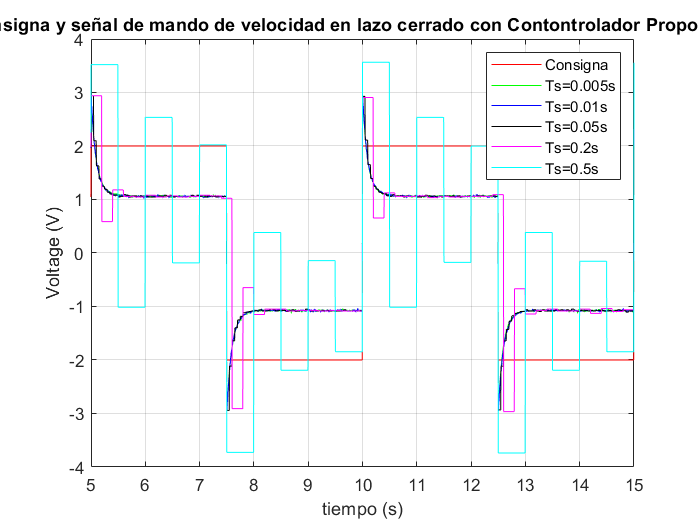


% error
figure()
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,1,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,1,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,1,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,1,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,1,:)],'c')
xlim([5 15]);ylim([-4 4]);
grid on;
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y señal de mando de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

Para analizar a partir de que Ts tendremos oscilaciones, hay que obtener la función de transferencia digital de lazo cerrado. Para ello, primeramente, se calculará la función de transferencia digital de lazo abierto usando para ello un mantenedor de orden cero. 

Una vez obtenido la expresión de polo, lo igualaremos a cero, ya que el sistema empezara a oscilar en ese preciso momento. En este caso, evaluando la ecuación con nuestros parámetros, obtenemos que el sistema empezara a oscilar a 0.2 segundos de tiempo de muestreo y como se puede ver en la imagen, la respuesta del sistema con este periodo de muestreo, la respuesta de color magenta, presenta un sobre impulso. A mayores tiempos de muestreo, la salida es aún más oscilante. 

# Ejercicio 4: Respuesta del sistema en lazo abierto para la señal del potenciómetro.

Abrir y ejecutar el modelo P1_Ex4.slx. Comprobar que es la respuesta típica de un sistema de tipo 1. 

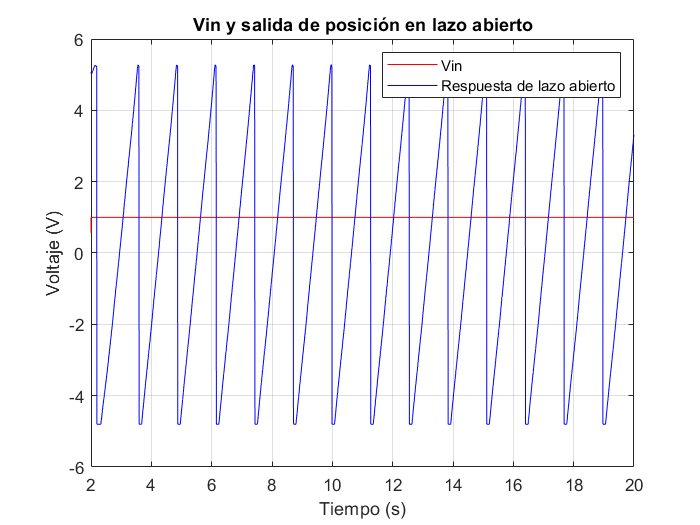

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Usar Simulink 
    addpath([pwd filesep 'E4']);
    open P1_Ex4.slx
    run P1_Ex4.slx
else % Cargar respuesta lazo abierto
    FileName   = 'OpenLoopPosition.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex4'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

% salida
figure
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,2,:)],'b')
xlim([2 20]);grid on;
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Vin y salida de posición en lazo abierto');
legend('Vin','Respuesta de lazo abierto');

En este caso, la respuesta de la planta en lazo abierto es una señal periódica con forma de onda de sierra, ya que la planta es de tipo 1. Con lo cual, a entradas tipo escalón obtendremos una señal tipo rampa. Por otra parte, la periodicidad ocurre por cada vuelta de eje del potenciómetro.

# Ejercicio 5: Respuesta del sistema en lazo cerrado con realimentación de posición.

Abrir y ejecutar el modelo P1_Ex5.slx. Comprobar cómo varía el error en estado estacionario para Kp= 1, 2 y 3, cambiando el bloque "Controlador Proporcional".

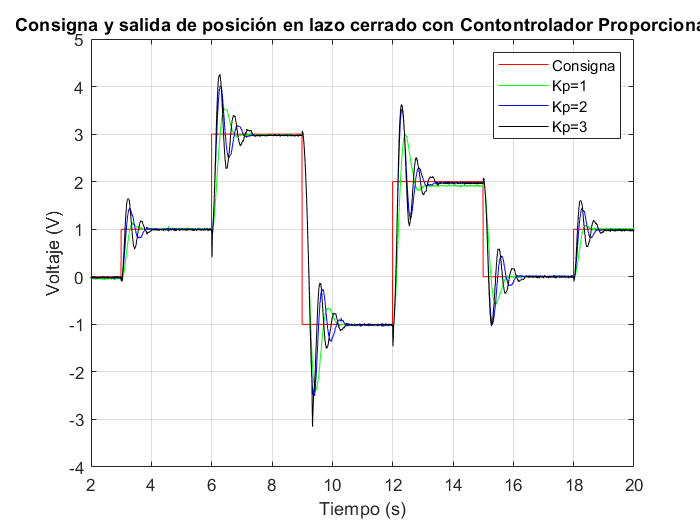

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Usar Simulink 
    addpath([pwd filesep 'E5']);
    open P1_Ex5.slx
    run P1_Ex5.slx
else % Cargar variables
    FileName   = 'Kp1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);   
    
    FileName   = 'Kp2.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Kp3.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex5'];
    File       = fullfile(FolderName, FileName);
    load(File);
end

% salida
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all; grid on;
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,1,:)],'k')
xlim([2 20]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=3');

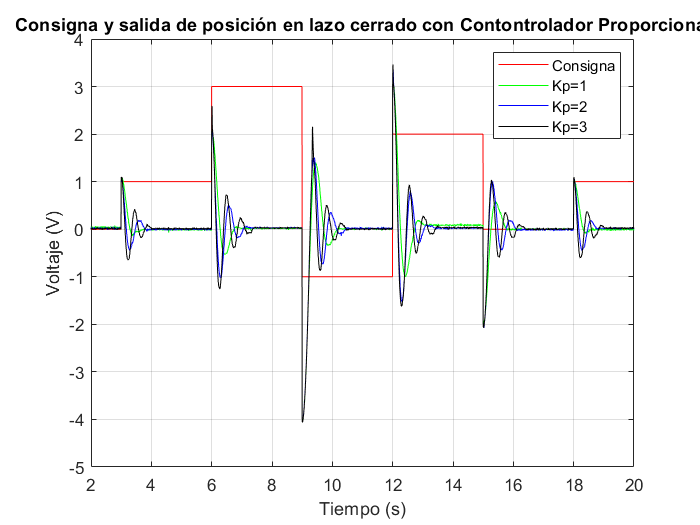


% error
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all; grid on;
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,2,:)],'k')
xlim([2 20]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=3');

En este caso, como el motor es de tipo 1, el error estacionario será cero, pero el sobre impulso y el tiempo de establecimiento variaran dependiendo de la ganancia del controlador. A mayor Kp, mayor es el sobre impulso y mayor el tiempo de establecimiento.

# Ejercicio 6: Evaluación experimental de las prestaciones del sistema en lazo cerrado con realimentación de posición. 

Abirir y ejecutar el modelo P1_Ex6.slx. Evaluar cómo varía la precisión y la estabilidad del sistema para diferentes periodos de muestreo.

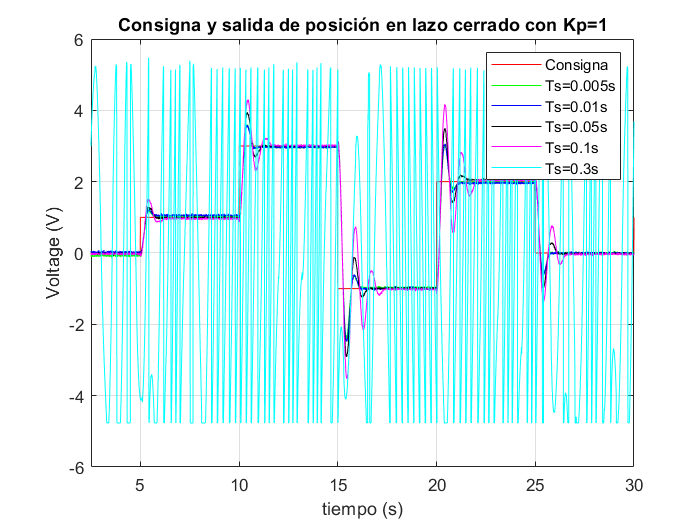

% Inicialización de variables
Tg= 0.005; % Tiempo de graficación [seg]
Ts=0.01; % Tiempo de muestreo
Vmax=5; % [V]
Vmin=-5; % [V]

if useExperimentalData
    % Usar Simulink 
    addpath([pwd filesep 'E6']);
    open P1_Ex6.slx
    run P1_Ex6.slx
else % Cargar variables
    FileName   = 'Ts005.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);   
    
    FileName   = 'Ts01.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts05.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts1.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
    
    FileName   = 'Ts3.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac1' filesep 'Ex6'];
    File       = fullfile(FolderName, FileName);
    load(File);
end

% salida
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all; grid on;
plot(Ts005.time, [Ts005.signals.values(:,3,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,3,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,3,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,3,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,3,:)],'c')
xlim([2.5 30]);
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de posición en lazo cerrado con Kp=1');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')

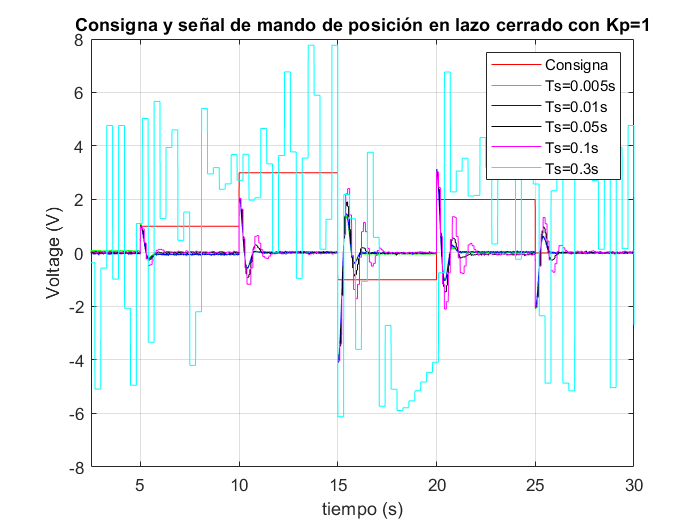


% error
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all; grid on;
plot(Ts005.time, [Ts005.signals.values(:,1,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,1,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,1,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,1,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,1,:)],'c')
xlim([2.5 30]);
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y señal de mando de posición en lazo cerrado con Kp=1');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')

En este caso también, para analizar a partir de qué valor el sistema se volverá inestable, como hemos hecho anteriormente, se ha digitalizado la planta con la ayuda de un mantenedor de orden cero, se ha obtenido el modelo digital de lazo cerrado y analizado estos polos. Evaluando el denominador mediante el criterio de estabilidad de Jury, se obtiene que el rengo de Ts para que el sistema sea estable es de 0 a 0.3 segundos.